% Parameters
T_range = 20:0.1:250; % Temperature range in Celsius
G_range = 800:10:1400; % Irradiance range in W/m²
num_T_points = length(T_range);
num_G_points = length(G_range);

% Solar Panel Constants
eta_ref_solar = 0.20; % Reference efficiency at 25°C and 1000 W/m²
alpha_solar = -0.004; % Temperature coefficient per °C
T_ref_solar = 25; % Reference temperature in °C
G_ref = 1000; % Reference irradiance in W/m²
gamma = 0.05; % Irradiance coefficient

% TEG Constants
eta_max_TEG = 0.10; % Maximum efficiency
T_opt_TEG = 80; % Optimal temperature in °C
sigma_TEG = 15; % Controls the spread of the efficiency curve
T_ambient = 25; % Ambient temperature in °C
delta_T_max = 50; % Maximum temperature rise at reference irradiance

% Weights for net efficiency calculation
w_solar = 0.7; % Solar panel contribution to net efficiency
w_TEG = 0.3; % TEG contribution to net efficiency

% Initialize efficiency arrays
efficiency_solar = zeros(num_T_points, num_G_points);
efficiency_TEG = zeros(num_T_points, num_G_points);
net_efficiency = zeros(num_T_points, num_G_points);

% Calculate efficiencies based on temperature and irradiance
for i = 1:num_T_points
    T = T_range(i); % Current temperature in °C
    
    for j = 1:num_G_points
        G = G_range(j); % Current irradiance in W/m²
        
        % Solar Panel Efficiency Calculation
        temp_diff_solar = T - T_ref_solar;
        irradiance_factor = (G / G_ref)^gamma;
        eta_solar = eta_ref_solar * (1 + alpha_solar * temp_diff_solar) * irradiance_factor;
        efficiency_solar(i, j) = max(0, eta_solar); % Ensure efficiency doesn't go below 0
        
        % TEG Efficiency Calculation
        T_h = T_ambient + (G / G_ref) * delta_T_max; % Hot-side temperature
        eta_TEG = eta_max_TEG * exp(-(T_h - T_opt_TEG)^2 / (2 * sigma_TEG^2));
        efficiency_TEG(i, j) = eta_TEG;
        
        % Net Efficiency Calculation
        net_efficiency(i, j) = w_solar * efficiency_solar(i, j) + w_TEG * efficiency_TEG(i, j);
    end
end

% Create a 3D table of values (Temperature, Irradiance, Efficiencies)
[T_grid, G_grid] = meshgrid(T_range, G_range);

% Calculate the product of irradiance and temperature
Irradiance_Times_Temperature = T_grid(:) .* G_grid(:);

% Create the table with the product as the third column
efficiency_table = table(T_grid(:), G_grid(:), Irradiance_Times_Temperature, efficiency_solar(:)*100, efficiency_TEG(:)*100, net_efficiency(:)*100, ...
    'VariableNames', {'Temperature_C', 'Irradiance_W_m2', 'Irradiance_Times_Temperature', 'Solar_Efficiency', 'TEG_Efficiency', 'Net_Efficiency'});

% Display the table in the command window
disp(efficiency_table);

    Temperature_C    Irradiance_W_m2    Irradiance_Times_Temperature    Solar_Efficiency    TEG_Efficiency    Net_Efficiency
    _____________    _______________    ____________________________    ________________    ______________    ______________

           20              800                        16000                  20.174             6.0653            15.941    
           20              810                        16200                  20.166             6.0653            15.936    
           20              820                        16400                  20.158             6.0653             15.93    
           20              830                        16600                   20.15             6.0653            15.925    
           20              840               


% Export the table to a CSV file
filename = 'efficiency_data_with_irradiance.csv';
writetable(efficiency_table, filename);
fprintf('Data has been written to %s\n', filename);

Data has been written to efficiency_data_with_irradiance.csv


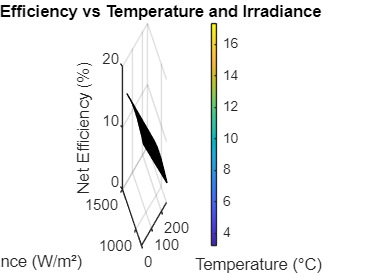


% Plotting the results (3D surface plot)
figure;
surf(T_range, G_range, net_efficiency' * 100); % Transpose net_efficiency for correct dimensions
xlabel('Temperature (°C)');
ylabel('Irradiance (W/m²)');
zlabel('Net Efficiency (%)');
title('Net Efficiency vs Temperature and Irradiance');
colorbar;
grid on;

% Export the graph as a PNG file
graph_filename = 'net_efficiency_plot.png';
saveas(gcf, graph_filename);

fprintf('Graph has been saved as %s\n', graph_filename);

Graph has been saved as net_efficiency_plot.png
